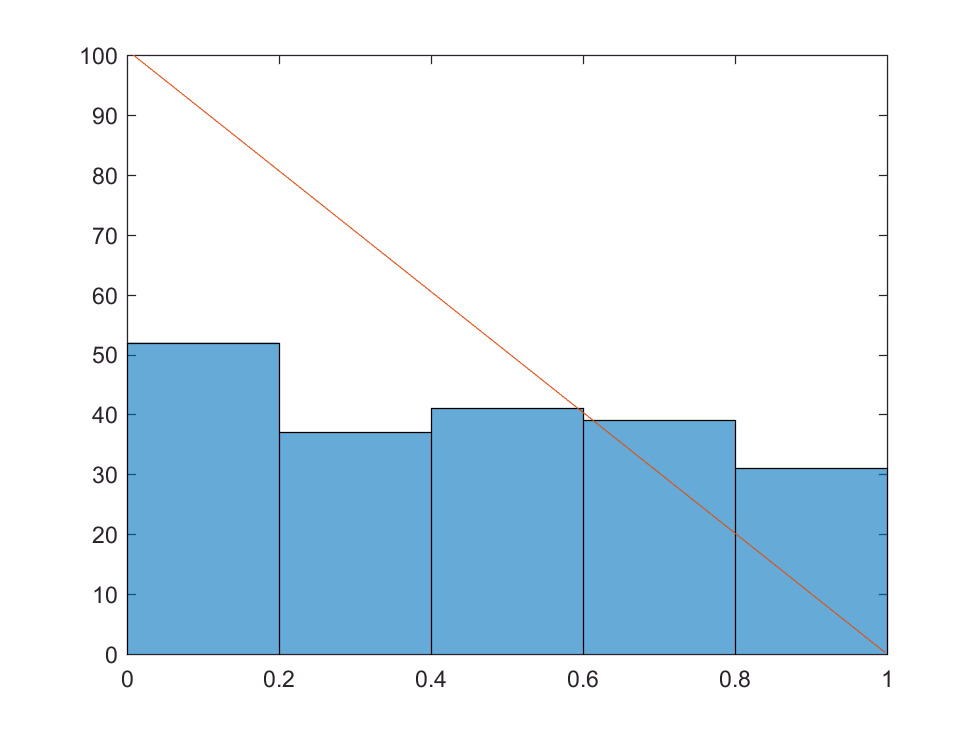

f=@(x)60.*x.*power((1-x),2);
c=2.0736;

A=rand(200,1);
y=1+A*(0-1);
B=rand(200,1);
ff=f(y)./c;
if any(B < ff)
    zeta = y;
else
    zeta = 1; 
end
%plot(zeta,A,'b .')
x=A;
y=zeta;

figure
histogram(zeta)
hold on
scale = 100/max(y);
plot((x),(y.*scale))
hold off